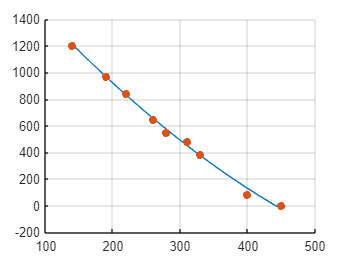

clc
clear
P = [1200 970 845 650 550 480 380 80 0];
Q = [140 190 220 260 280 310 330 400 450];
n = length(P);
syms p(q);
p(q) = curve_fit(Q,P);
p_error = zeros(1,n);
for i = 1 : n
   p_error(i) = abs(P(1,i)-subs(p(q),Q(i)));
end
sum_error = 0;
for i = 1 : n
    sum_error = p_error(i)*p_error(i);
end
hold all
fplot(p(q),[140,450]);
scatter(Q,P,'filled');
grid on

function [output] = curve_fit(x,y)
x1 = sum(x);
y1 = sum(y);
N = length(x);
x2 = 0;
for i = 1 : N
    x2 = x2 + x(i)^2;
end
x3 = 0;
for i = 1 : N
    x3 = x3 + x(i)^3;
end
x4 = 0;
for i = 1 : N
    x4 = x4 + x(i)^4;
end
xy = 0;
for i = 1 : N
    xy = xy + x(i)*y(i);
end
x2y = 0;
for i = 1 : N
    x2y = x2y + (x(i)^2)*y(i);
end
A = [x4 x3 x2 ; x3 x2 x1 ; x2 x1 N];
B = [x2y ; xy ; y1];
coeff = gauss (A,B);

syms output(p)
c = vpa(coeff(1));
b = vpa(coeff(2));
a = vpa(coeff(3));
output(p) = a + b*p + c*p*p;
end

function output = gauss(A,B)
n = length(B);
AOB = [A B];
Answer = zeros(n,1);
for i = 1 : n
    for j = i+1 : n
        ratio = AOB(j,i) / AOB(i,i);
        AOB(j,:) = AOB(j,:) - ratio*AOB(i,:);
    end
end
for i = 1 : n
    B(i) = AOB(i,n+1);
end
for i = n : -1 : 1
    Answer(i) = B(i);
    for j = i+1 : n
        Answer(i) = Answer(i) - AOB(i,j)*Answer(j);
    end
    Answer(i) = Answer(i)/AOB(i,i);
end
output = Answer;
end